clear; close all;

% Permissivity
eps0 = 8.854187817e-12;

% Grid & domain
Nx = 10; Ny = 10; Nz = 10; % number of grid points in each dir
Lx = 1.0; Ly = 1.0; Lz = 1.0; % grid dimensions (meters) - currently cube
dx = Lx/Nx; dy = Ly/Ny; dz = Lz/Nz; 
xl = linspace(0, Lx, Nx);
yl = linspace(0, Ly, Ny);
zlb = zeros(Nx, Ny);
zlt = zeros(Nx, Ny);

z_bot = @(x, y) 4/3*cos(x/2) - y/5; % function that describes z of top and bottom plates
z_top = @(x, y) sin(x) + cos(y*3) + 5; 
xy_top = @(x, y) x.^2 - y;
xy_bottom = @(x, y) x.^2 + 3*y.^2;
C = 1; % xy_top and xy_bottom should both evaluate to be less than or equal to C
delt_V = 1; % Voltage across the plates
A_patch = dx*dy; % area of one patch

% Plate geometry (rectangular plates)
plate_width = 0.6*Lx;
plate_height = 0.6*Ly;
plate_thickness = 2*dz;
gap = 0.4*Lz;  % approximate center-to-center gap

% Centers
Cx = Lx/2; % center of plates
Cy = Ly/2;

%[X, Y, Z] = ndgrid(x, y, z); % make grid, ndgrid will allow you to use i, j, k indicies to get x, y, z coordinates
%Z_bot = X.^0.5 + Y;

V = transpose(zeros(1, Nx*2*Nz));
V(Nx*Nz:Nx*Nz*2) = delt_V; % top plate voltage is voltage difference, bottom plate stays 0

% solving for voltage
r = zeros(Nx*Nz*2, 3); % r is list/vector of all the position vectors
for i = 1:Nx
    for j = 1:Ny
        zlb(i, j) = z_bot(i, j);
        zlt(i, j) = z_top(i, j);
        r((i-1)*Nx + j, :) = [i, j, z_bot(i, j)];
        r((i-1)*Nx + j + Nx*Ny, :) = [i, j, z_top(i, j)];
    end
end
r

r =     1.0000    1.0000    0.9701
    1.0000    2.0000    0.7701
    1.0000    3.0000    0.5701
    1.0000    4.0000    0.3701
    1.0000    5.0000    0.1701
    1.0000    6.0000   -0.0299
    1.0000    7.0000   -0.2299
    1.0000    8.0000   -0.4299
    1.0000    9.0000   -0.6299
    1.0000   10.0000   -0.8299


% G is matrix used to relate V at each point to rho, charge density
% Gij = Aj/(4 pi epsilon |ri - rj|), ri is vector to center of patch on 0
% plate, rj is vector to center of patch on V = 1 plate
% there are Nx*Ny patches on each plate

G = zeros(Nx*Ny, Nx*Ny);

for i = 1:(Nx*Ny*2)
    for j = 1:(Nx*Ny*2)
        deltR = r(i, :) - r(j, :); % ri - rj
        if (deltR ~= 0)
            G(i, j) = 1/norm(deltR);
        end
    end
end
G = G * A_patch /(4 * pi * eps0) % multiply by the area of the patches and other constants,

G = 1.0e+07 *

         0         0         0         0         0         0         0         0         0         0         0    5.7749    3.7572    2.6974    2.0861    1.6954    1.4260    1.2297    1.0804    0.9632         0    3.4911    2.8172    2.2605    1.8533    1.5573    1.3371    1.1688    1.0367    0.9306         0    2.4277    2.1475    1.8577    1.6045    1.3964    1.2281    1.0918    0.9803    0.8881         0    1.8763    1.7309    1.5632    1.3997    1.2525    1.1250    1.0161    0.9234    0.8443
         0         0         0         0         0         0         0         0         0         0    6.2583         0    5.7749    3.7572    2.6974    2.0861    1.6954    1.4260    1.2297    1.0804    3.7425         0    3.4911    2.8172    2.2605    1.8533    1.5573    1.3371    1.1688    1.0367    2.5600         0    2.4277    2.1475    1.8577    1.6045    1.3964    1.2281    1.0918    0.9803    1.9541         0    1.8763    1.7309    1.5632    1.3997    1.2525    1.1250    

% for uneven patch sizes do this step inside of the for loops
% Know that G * rho = V, so can calc rho
V

V =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


rho = V \ G

rho = 1.0e+07 *

    0.8914    0.9637    0.9592    0.9945    0.9654    0.9656    0.9184    0.8903    0.8341    0.7781    0.9165    0.9957    0.9852    1.0231    0.9881    0.9883    0.9361    0.9066    0.8469    0.7879    0.8983    0.9717    0.9586    0.9933    0.9583    0.9579    0.9080    0.8803    0.8241    0.7666    0.8596    0.9218    0.9090    0.9384    0.9069    0.9061    0.8617    0.8373    0.7874    0.7331    0.8288    0.8836    0.8714    0.8976    0.8689    0.8682    0.8281    0.8061    0.7609    0.7076



% charge on plate is then sum of charge density on each patch times area of
% patch
Q_tot = sum(rho)*A_patch % equal patch sizes

Q_tot = 2.3682e+07

C = Q_tot/delt_V % capacitance

C = 2.3682e+07

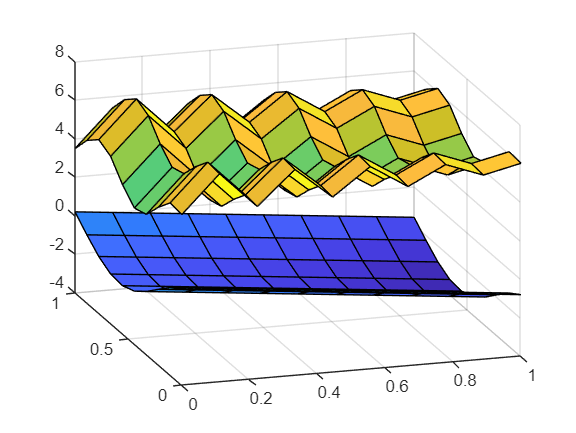


figure;
surf(xl, yl, zlb);
hold on;
surf(xl, yl, zlt);